% % % % % % % % % Este sección del script fue creado por:
% % % % % % % % % % Autores: Andrés Felipe Baez Aponte

% % % % % % % % % % Limpia registros y cierra figuras
clear all
close all
% 
% % % % % % % Valor de Al del material del Toroide seleccionado.
AL = 4.5;
% 
% % % % % % %  Diametro del alambre de cobre en [mm]
Dcobre = 0.511;               % d en formula del libro
% 
% % % % % % %  Diametro interno del Toroide en [in]
Di = 0.120;
Di = Di*25.4;            % % Valor en [mm]


% % % % % %  Radio y perimetro medio entre DI y Dcobre estan en [mm]
Rmed = (Di/2) - (Dcobre/2)

Rmed =    1.268500000000000


Pmed = 2*pi*Rmed

Pmed =    7.970220562157303



% % % % % % Numero de vueltas Maximos para ese Toroide
Nmax = ( Pmed / Dcobre)*0.90

Nmax =   14.037570461725192



% % % % % %  numero de vueltas a diseñar, seleccionado a partir de Nmax
N1 = 2

N1 =      2


N2 = 3

N2 =      3


% % % % % %  Encontrar el valor de Ltotal
syms L
NT = N1+N2;


LA1 = double(solve(N1==100*sqrt(L/AL),L))*(1e-6) 

LA1 =      1.800000000000000e-09


LA2 = double(solve(N2==100*sqrt(L/AL),L))*(1e-6) 

LA2 =      4.050000000000000e-09



L_TOTAL = LA1 + LA2 + 2*sqrt(LA1*LA2)

L_TOTAL =      1.125000000000000e-08


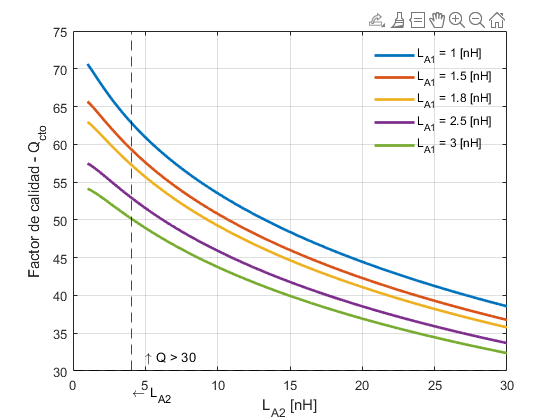


% % % % % % % % % Esta sección del script fue creado por:
% % % % % % % % % % Autores: Andrés Felipe Baez Aponte
% % % % % % % % % %          Cristian Chayanne Gomez 
close all
% % % % % % % % % % Declarar variables simbolicas
syms Xa2 La1 

% % % % % % % % % % Definir valores
L_a1 = [ 1, 1.5, LA1/1e-9, 2.5, 3].*1e-9;
f = 150e6;
w=2*pi*f;
Rl=3600;
Rs=600;
Qb=130;
Xa1=w*La1;

Q_sym = calculo_Q(w,Rl,Rs,Qb,Xa1,Xa2,La1);

x = linspace(1e-9,30e-9,1000).*w;

for i = 1:length(L_a1)
    Qs(i) = subs(Q_sym,La1,L_a1(i));
end

for i = 1:length(Qs)
    Q = Qs(1,i);
    Q = double(subs(Q,Xa2,x));
    plot((x/w)/(1e-9),Q,"LineWidth", 2);
    hold on
    grid on
end
yline(30,'--k')
xline(LA2/1e-9,'--k')
text(LA2/1e-9,27,'\leftarrow L_{A2}' )
text(5,32,'\uparrow Q > 30' )
ylabel('Factor de calidad - Q_{cto}')
xlabel("L_{A2} [nH]")
legend( "L_{A1} = 1 [nH]", "L_{A1} = 1.5 [nH]", "L_{A1} = 1.8 [nH]", "L_{A1} = 2.5 [nH]", "L_{A1} = 3 [nH]")
legend("boxoff")

set(gcf,"visible","on")
saveas(gcf, "Qcto.eps", "epsc")


% % % % % % % % Calcular valor del capacitor
syms C

W0 = 2*pi*f == 1/(sqrt(L_TOTAL*C));

C = double((solve(W0,C)))

C =      1.000703048319386e-10


function y = myRp(r1,r2)
    y = (r1*r2)/(r1+r2);
end



function Q = calculo_Q(w,Rl,Rs,Qb,Xa1,Xa2,La1)

% % % % % % % % % % Definir ecuaciones relacionadas
X2 = Xa1 + Xa2 + 2*sqrt(Xa1*Xa2);
n = sqrt(Xa1/X2);
Ra1 = Qb * Xa1;
Ra2 = Qb * Xa2;
R2 = (Qb^2 * X2^2) / (Ra1 + Ra2);

% % % % % % % % % % Calculo de RT del circuito
Rp1 = (myRp(Rs,Ra1))/n^2;
Rp2 = myRp(Rl,R2);
RT = myRp(Rp1,Rp2);

% % % % % % % % % Cálculo factor de calidad (Q) del circuito
Q = RT/X2;

end